# 第2章 离散时间信号和系统分析基础

## 2.7 z变换

### 2.7.2 z变换的收敛域

#### `Ch2_7_1`

`已知系统函数`


$$H\left(z\right)=\frac{\sum_{r=0}^M b_r z^{-r} }{1-\sum_{k=1}^N a_k z^{-k} }=\frac{1+0\ldotp 5z^{-1} }{1-z^{-1} +0\ldotp 5z^{-2} }$$


`绘制系统函数``的三维``幅频``、``相频响应``图。`

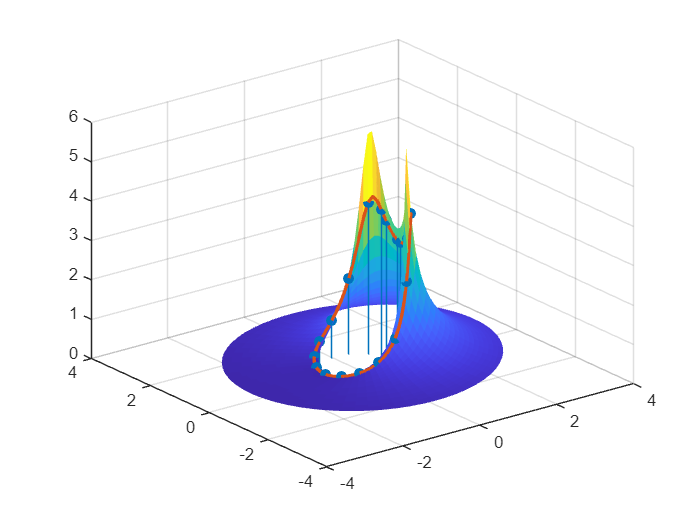

%系统函数
b=[0 1 0.5];
a=[1 -1 0.5];
r_=0.5*sqrt(2)+0.2:0.1:3;
phi_=0:0.1:2.2*pi;
[r, phi]=meshgrid(r_, phi_);
Z=r.*exp(phi.*1i);
%采样点
z_=ones(1, ceil(length(phi_)/4)).*exp(phi_((1:4:length(phi_))).*1i);
h=(z_+0.5)./(z_.^2-z_+0.5);
H=(Z+0.5)./(Z.^2-Z+0.5);
figure;
%幅面
[x,y,z]=pol2cart(phi,r,abs(H));
surf(x,y,z);
shading flat;
%alpha(0.3); 
%采样点
[x, y, z]=pol2cart(phi_((1:4:length(phi_))), ones(1, ceil(length(phi_)/4)),abs(h));
hold on;
stem3(x,y,z,'filled');
hold on;
%采样线
z_=ones(1, length(phi_)).*exp(phi_.*1i);
h=(z_+0.5)./(z_.^2-z_+0.5);
[x, y, z]=pol2cart(phi_,ones(1,length(phi_)),abs(h));
%绘制采样线
plot3(x,y,z,'LineWidth',2);

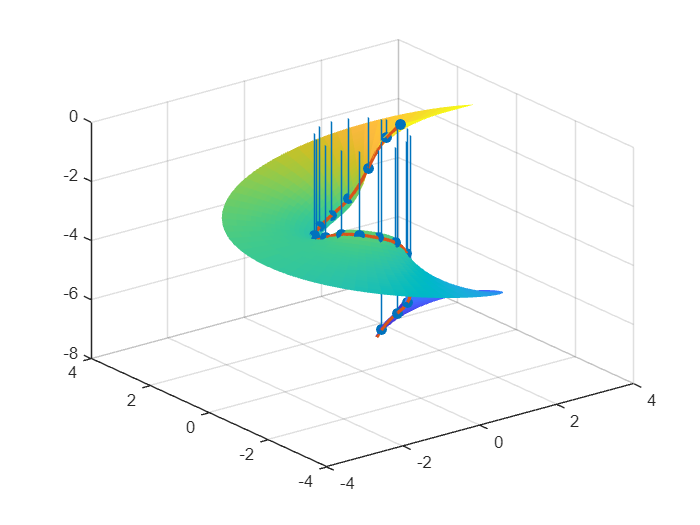

%相面
figure;
[x,y,z]=pol2cart(phi,r,unwrap(angle(H)));
surf(x,y,z);
shading flat;
%alpha(0.3);
%采样点
z_=ones(1, ceil(length(phi_)/4)).*exp(phi_((1:4:length(phi_))).*1i);
h=(z_+0.5)./(z_.^2-z_+0.5);
[x, y, z]=pol2cart(phi_((1:4:length(phi_))), ones(1, ceil(length(phi_)/4)),unwrap(angle(h)));
%采样点
hold on;
stem3(x,y,z,'filled');
hold on;
%采样线
z_=ones(1, length(phi_)).*exp(phi_.*1i);
h=(z_+0.5)./(z_.^2-z_+0.5);
[x, y, z]=pol2cart(phi_,ones(1,length(phi_)),unwrap(angle(h)));
%绘制采样线
plot3(x,y,z,'LineWidth',2);